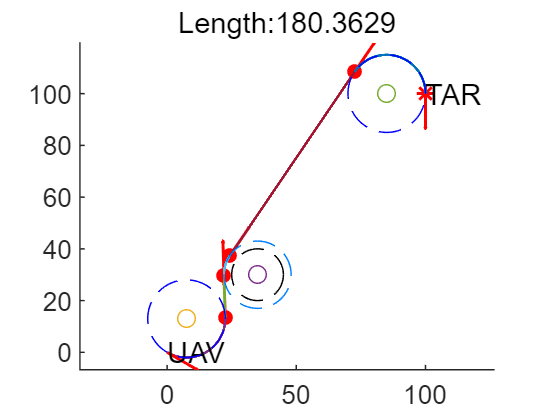

clear all
%% 定义函数输入
Start_Point = [0,0,-pi/6];
End_Point = [100,100,-pi/2];
r_s=15;
r_e=r_s;

sure=3;
R=10+sure;

Stepsize=0.01;
Avoid_Center = [35,30;
                60,50];

check=[1,2];

%% 寻找Dubins路径
[param_all,param_best(1)] = DubinsAvoid(Start_Point, End_Point,Avoid_Center(1,:),r_s,r_e,R,Stepsize,check);
figure(1)
DrawD_bset(param_best(1),sure)

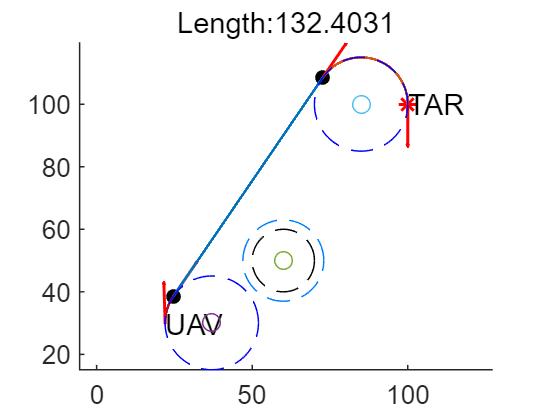


Start_newPoint=[param_best(1).point(:,3)',param_best.vtheta(2)];
[param_all_new,param_best(2)] = DubinsAvoid(Start_newPoint,End_Point,Avoid_Center(2,:),r_s,r_e,R,Stepsize,check);
figure(2)
DrawD_bset(param_best(2),sure)

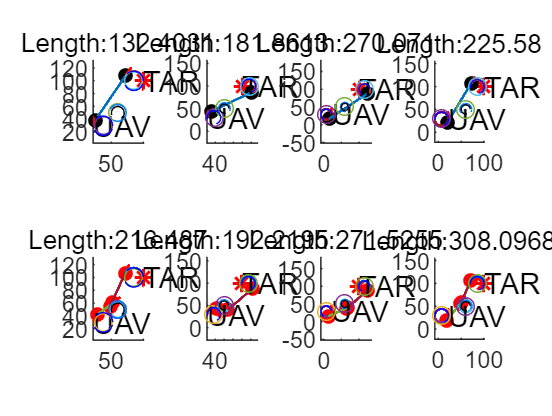


% figure('Name','3')
% for i=1:4
%     for j=1:2
%         DrawD_bset(param_all(j,i),sure)
%     end
% end

figure(3)
hold on
for j=1:2
    for i=1:4
        subplot(2,4,i+4*(j-1));
%         DrawD_bset(param_all(j,i),sure)
        DrawD_bset(param_all_new(j,i),sure)
    end
end


% subplot(2,2,1);
% plot(param_all(2,1).path(1,:),param_all(2,1).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
% subplot(2,2,2);
% plot(param_all(2,2).path(1,:),param_all(2,2).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
% subplot(2,2,3);
% plot(param_all(2,3).path(1,:),param_all(2,3).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
% subplot(2,2,4);
% plot(param_all(2,4).path(1,:),param_all(2,4).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;

